clearvars; close all;
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));
LPath = 'D:\Profile\qse\Files\_EDMRoC pinSC\IV curve\SuSi\a-Si_pin_Solar_Cell_AM1p5G.mat';
load(LPath)

CONVERSION_TO_J = 1000*100; % Conversion in mA over cm2

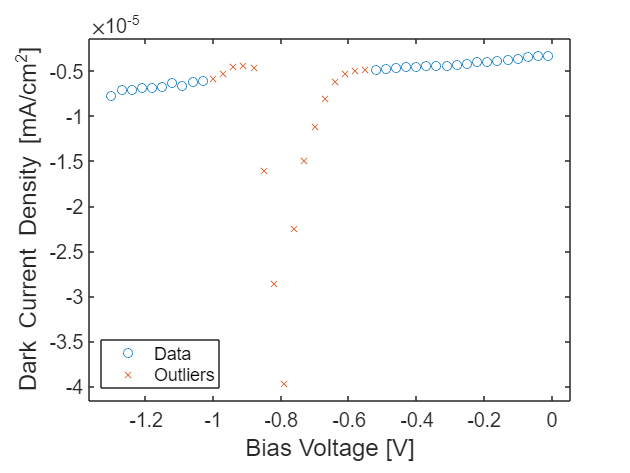

Vrange = [-1.4 -1 -0.55 0.];
idxLow = (V > Vrange(1) & V < Vrange(2)) | (V > Vrange(3) & V < Vrange(4));

VLow = V(idxLow); ILow = I(idxLow);
figure()
tL = tiledlayout('flow');
nexttile
plot(VLow, ILow*CONVERSION_TO_J, 'o')
hold on
plot(V(V >= Vrange(2) & V <= Vrange(3)), I(V >= Vrange(2) & V <= Vrange(3))*CONVERSION_TO_J, 'x')
legendFirstTile(tL);
labelAxesFig(tL, "Bias Voltage [V]", 'Dark Current Density [mA/cm^2]')
lgd = legendFirstTile(tL, {'Data', 'Outliers'});
lgd.Location = "southwest";

xlim(setAxLim(VLow, 0.05));
ylim(setAxLim(I(V<0)*CONVERSION_TO_J, 0.05))

Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';
exportFig(gcf, Opt.SFolder, 'IV outliers at negative V', '.png')

Graphics not exported


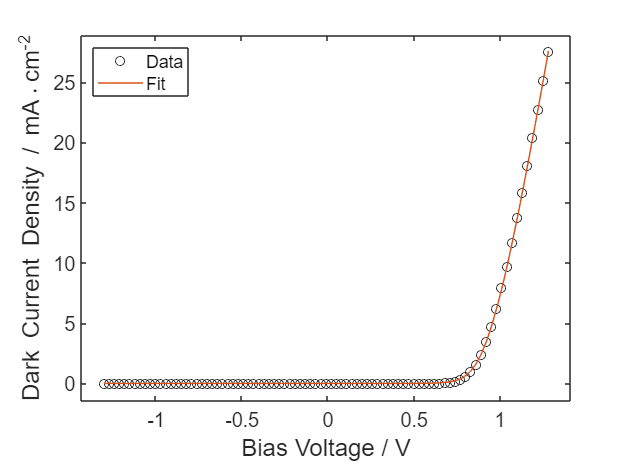

iBest = 9;
Is_ = bestFit.Is1(iBest);
Rs_ = bestFit.Rs(iBest);
Rsh_ = bestFit.Rsh(iBest);
alpha_ = bestFit.alpha1(iBest);
Ifit = onediodemodel(V, I, [Is_, Rs_, Rsh_, alpha_]);
Ifit = Ifit;

figure()
tL = tiledlayout('flow');
nexttile;

plot(V, I*CONVERSION_TO_J, 'o', 'Color', 'black')
hold on
plot(V, Ifit*CONVERSION_TO_J, 'Color', '#D95319')

lgd = legendFirstTile(tL, {'Data', 'Fit'});
lgd.Location = "northwest";

xlim(setAxLim(V, 0.05));
ylim(setAxLim(I*CONVERSION_TO_J, 0.05))
grid off
legendFirstTile(tL);
labelAxesFig(tL, "Bias Voltage / V", 'Dark Current Density / mA{\cdot}cm^{-2}')

Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';
exportFig(gcf, Opt.SFolder, 'IV SuSi', '.png')

Graphics not exported


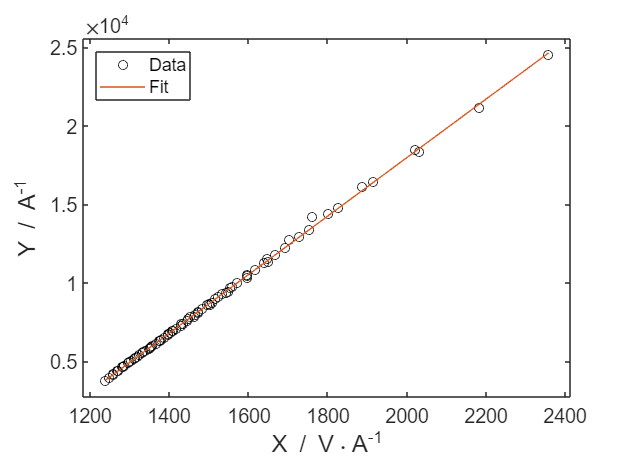

idxStart = 75;
nI = numel(I);
ny = (nI - idxStart + 1)*(nI - idxStart)/2;
[x, y] = deal(zeros(ny, 1)); 
iy = 1;
for i0 = idxStart:nI - 1
    I0 = I(i0);
    V0 = V(i0);
    for ii = i0 + 1:nI
        y(iy) = log(I(ii)/I0)/(I(ii)-I0);
        x(iy) = (V(ii)-V0)/(I(ii)-I0);
        iy = iy + 1;
    end
end

xDummy = linspace(min(x), max(x), 1000);
figure()
tL = tiledlayout('flow'); nexttile
plot(x, y, 'o', 'Color', 'black')
hold on
plot(xDummy, Fit1{iBest}.scale*Fit1{iBest}.pfit(1)*xDummy + Fit1{iBest}.scale*Fit1{iBest}.pfit(2))
xlim(setAxLim(x, 0.05))
ylim(setAxLim(y, 0.05))
labelAxesFig(tL, 'X / V{\cdot}A^{-1}', 'Y / A^{-1}');
lgd = legendFirstTile(tL, ["Data", "Fit"]);
lgd.Location = "northwest";

exportFig(gcf, Opt.SFolder, 'IV SuSi_1', '.png')

Graphics not exported


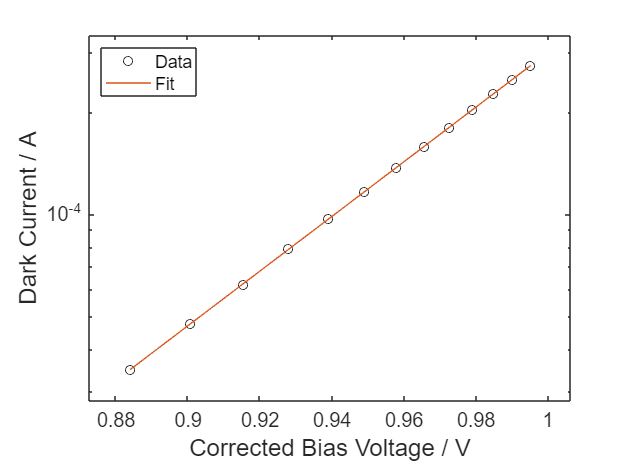

Rs_ = -Fit1{iBest}.pfit(2)/Fit1{iBest}.pfit(1);
Vc = V(idxStart:end) - I(idxStart:end)*Rs_; % Corrected voltage values
lnI = log(I(idxStart:end));

xDummy = linspace(min(Vc), max(Vc), 1000);
figure()
tL = tiledlayout('flow');
nexttile
semilogy(Vc, exp(lnI), 'o', 'Color', 'black')
hold on
semilogy(xDummy, exp( ...
    Fit2{iBest}.scale*Fit2{iBest}.pfit(1)*xDummy + Fit2{iBest}.scale*Fit2{iBest}.pfit(2)))
xlim(setAxLim(Vc, 0.1))
ylim(exp(setAxLim(lnI, 0.1)))
labelAxesFig(tL, 'Corrected Bias Voltage / V', 'Dark Current / A');
lgd = legendFirstTile(tL, ["Data", "Fit"]);
lgd.Location = "northwest";

exportFig(gcf, Opt.SFolder, 'IV SuSi_2', '.png')

Graphics not exported


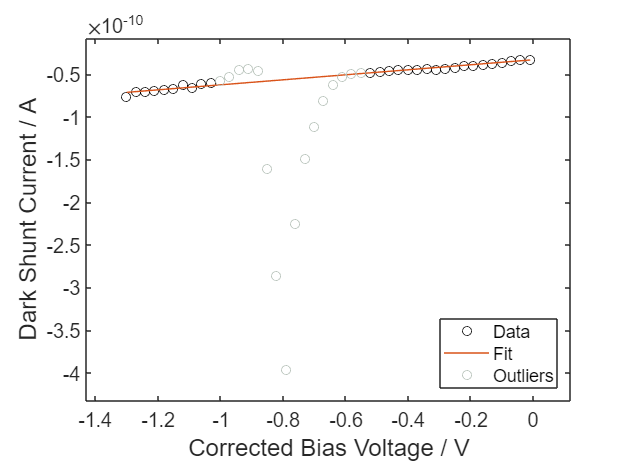

load("GrayColorResiduals.mat");
Vrange = [-1.4 -1 -0.55 0.];
idxLow = (V > Vrange(1) & V < Vrange(2)) | (V > Vrange(3) & V < Vrange(4));

idxLowNot = ~idxLow & V<0;
VLow = V(idxLow); ILow = I(idxLow);
alpha1_ = Fit1{iBest}.scale*Fit1{iBest}.pfit(1);
Is1_ = exp(Fit1{iBest}.scale*Fit2{iBest}.pfit(2));
Vc = V - I*Rs_;
I1 = Is1_*(exp(alpha1_*Vc) - 1);

I_ = ILow - I1(idxLow);
Inot = I(idxLowNot) - I1(idxLowNot);
V_ = VLow;
Vc_ = Vc(idxLow);
xDummy = linspace(min(Vc_), max(Vc_), 1000);
figure()
tL = tiledlayout('flow'); nexttile
plot(Vc_, I_, 'o', 'Color', 'black')
hold on
plot(xDummy, Fit3{iBest}.scale*Fit3{iBest}.pfit(1)*xDummy + Fit3{iBest}.scale*Fit3{iBest}.pfit(2))
plot(Vc(idxLowNot), Inot, 'o', 'Color', GrayColorResiduals)
xlim(setAxLim(Vc_, 0.1))
ylim(setAxLim(Inot, 0.1))
labelAxesFig(tL, 'Corrected Bias Voltage / V', 'Dark Shunt Current / A');
lgd = legendFirstTile(tL, {'Data', 'Fit', 'Outliers'});
lgd.Location = "southeast";

exportFig(gcf, Opt.SFolder, 'IV SuSi_3', '.png')

Graphics not exported


# RMSD plot

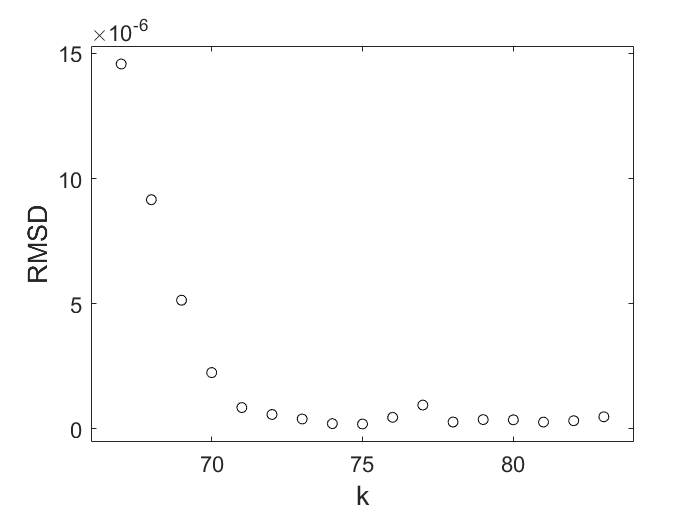

figure()
tL = tiledlayout('flow'); nexttile
plot(bestFit.IDX_START_INITIAL:bestFit.IDX_START_FINAL, bestFit.Rmsd, 'o', 'Color', 'black')
xlim([(bestFit.IDX_START_INITIAL - 1), (bestFit.IDX_START_FINAL + 1)])
ylim(setAxLim(bestFit.Rmsd, 0.05))
labelAxesFig(tL, "k", "RMSD")
exportFig(gcf, Opt.SFolder, 'IV susi RMSD vs k', 'png')

clearvars; close all;
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));
LPath = 'D:\Profile\qse\Files\_EDMRoC pinSC\IV curve\SuSi\a-Si_pin_Solar_Cell_AM1p5G.mat';
load(LPath)

for ii = 1:numel(Fit1)
    latexStrMat(1, ii) = sprintf("%i", (bestFit.IDX_START_INITIAL + ii - 1));
    latexStrMat(2, ii) = sprintf("$%.2f \\pm %.2f$", bestFit.alpha1(ii), bestFit.alpha1Std(ii));
    latexStrMat(3, ii) = sprintf("$%.2f \\pm %.2f$", bestFit.n1(ii), bestFit.n1Std(ii));
    latexStrMat(4, ii) = sprintf("$%.3f \\pm %.3f$", bestFit.Rs(ii)*1e-3, bestFit.RsStd(ii)*1e-3);
    latexStrMat(5, ii) = sprintf("$%.2f \\pm %.2f$", bestFit.Is1(ii)*1e12, bestFit.Is1Std(ii)*1e13);
    latexStrMat(6, ii) = sprintf("$%.1f \\pm %.1f$", bestFit.Rsh(ii)*1e-9, bestFit.RshStd(ii)*1e-9);
    latexStrMat(7, ii) = sprintf("$%.3f$", bestFit.Rmsd(ii)*1e7);
    latexStr(ii) = strjoin(latexStrMat(:, ii), '    &     ');
    latexStr(ii) = strjoin([latexStr(ii), "\\"], '');
end
disp(strjoin(latexStr, '\n'))

67    &     $20.43 \pm 0.12$    &     $1.91 \pm 0.03$    &     $1.122 \pm 0.007$    &     $0.48 \pm 0.13$    &     $34.0 \pm 0.8$    &     $145.768$\\
68    &     $20.24 \pm 0.11$    &     $1.92 \pm 0.03$    &     $1.104 \pm 0.006$    &     $0.59 \pm 0.13$    &     $34.0 \pm 0.8$    &     $91.554$\\
69    &     $20.01 \pm 0.10$    &     $1.95 \pm 0.03$    &     $1.088 \pm 0.005$    &     $0.73 \pm 0.13$    &     $34.0 \pm 0.8$    &     $51.401$\\
70    &     $19.73 \pm 0.09$    &     $1.97 \pm 0.03$    &     $1.072 \pm 0.005$    &     $0.95 \pm 0.12$    &     $34.0 \pm 0.8$    &     $22.502$\\
71    &     $19.41 \pm 0.07$    &     $2.01 \pm 0.03$    &     $1.059 \pm 0.004$    &     $1.26 \pm 0.11$    &     $34.0 \pm 0.8$    &     $8.516$\\
72    &     $19.11 \pm 0.05$    &     $2.04 \pm 0.03$    &     $1.048 \pm 0.003$    &     $1.62 \pm 0.09$    &     $34.0 \pm 0.8$    &     $5.752$\\
73    &     $18.85 \pm 0.03$    &     $2.07 \pm 0.02$    &     $1.041 \pm 0.002$    &     $2.02 \pm 0

latexStrMat(1, ii + 1) = "avg.";
latexStrMat(2, ii + 1) = sprintf("$%.2f \\pm %.2f$", mean(bestFit.alpha1), bestFit.alpha1Std(ii));
latexStrMat(3, ii + 1) = sprintf("$%.2f \\pm %.2f$", bestFit.n1(ii), bestFit.n1Std(ii));
latexStrMat(4, ii + 1) = sprintf("$%.3f \\pm %.3f$", bestFit.Rs(ii)*1e-3, bestFit.RsStd(ii)*1e-3);
latexStrMat(5, ii + 1) = sprintf("$%.2f \\pm %.2f$", bestFit.Is1(ii)*1e13, bestFit.Is1Std(ii)*1e13);
latexStrMat(6, ii + 1) = sprintf("$%.1f \\pm %.1f$", bestFit.Rsh(ii)*1e-9, bestFit.RshStd(ii)*1e-9);
latexStrMat(7, ii + 1) = sprintf("$%.3f$", bestFit.Rmsd(ii)*1e7);

for ii = 1:numel(Fit1)
    latexStr2(ii) = strjoin(latexStrMat(1:5, ii), '    &     ')
    latexStr2(ii) = strjoin([latexStr2(ii), latexStrMat(7, ii)], '    &     ');
    latexStr2(ii) = strjoin([latexStr2(ii), "\\"], '');
end

latexStr2 = 1×17 string array
    "67    &     $20.43 \pm 0.12$    &     $1.91 \pm 0.03$    &     $1.122 \pm 0.007$    &     $0.48 \pm 0.13$"    "68    &     $20.24 \pm 0.11$    &     $1.92 \pm 0.03$    &     $1.104 \pm 0.006$    &     $0.59 \pm 0.13$    &     $91.554$\\"    "69    &     $20.01 \pm 0.10$    &     $1.95 \pm 0.03$    &     $1.088 \pm 0.005$    &     $0.73 \pm 0.13$    &     $51.401$\\"    "70    &     $19.73 \pm 0.09$    &     $1.97 \pm 0.03$    &     $1.072 \pm 0.005$    &     $0.95 \pm 0.12$    &     $22.502$\\"    "71    &     $19.41 \pm 0.07$    &     $2.01 \pm 0.03$    &     $1.059 \pm 0.004$    &     $1.26 \pm 0.11$    &     $8.516$\\"    "72    &     $19.11 \pm 0.05$    &     $2.04 \pm 0.03$    &     $1.048 \pm 0.003$    &     $1.62 \pm 0.09$    &     $5.752$\\"    "73    &     $18.85 \pm 0.03$    &     $2.07 \pm 0.02$    &     $1.041 \pm 0.002$    &     $2.02 \pm 0.06$    &     $3.952$\\"    "74    &     $18.68 \pm 0.02$    &     $2.09 \pm 0.02$    &     $1.036 \

latexStr2 = 1×17 string array
    "67    &     $20.43 \pm 0.12$    &     $1.91 \pm 0.03$    &     $1.122 \pm 0.007$    &     $0.48 \pm 0.13$    &     $145.768$\\"    "68    &     $20.24 \pm 0.11$    &     $1.92 \pm 0.03$    &     $1.104 \pm 0.006$    &     $0.59 \pm 0.13$"    "69    &     $20.01 \pm 0.10$    &     $1.95 \pm 0.03$    &     $1.088 \pm 0.005$    &     $0.73 \pm 0.13$    &     $51.401$\\"    "70    &     $19.73 \pm 0.09$    &     $1.97 \pm 0.03$    &     $1.072 \pm 0.005$    &     $0.95 \pm 0.12$    &     $22.502$\\"    "71    &     $19.41 \pm 0.07$    &     $2.01 \pm 0.03$    &     $1.059 \pm 0.004$    &     $1.26 \pm 0.11$    &     $8.516$\\"    "72    &     $19.11 \pm 0.05$    &     $2.04 \pm 0.03$    &     $1.048 \pm 0.003$    &     $1.62 \pm 0.09$    &     $5.752$\\"    "73    &     $18.85 \pm 0.03$    &     $2.07 \pm 0.02$    &     $1.041 \pm 0.002$    &     $2.02 \pm 0.06$    &     $3.952$\\"    "74    &     $18.68 \pm 0.02$    &     $2.09 \pm 0.02$    &     $1.036 

latexStr2 = 1×17 string array
    "67    &     $20.43 \pm 0.12$    &     $1.91 \pm 0.03$    &     $1.122 \pm 0.007$    &     $0.48 \pm 0.13$    &     $145.768$\\"    "68    &     $20.24 \pm 0.11$    &     $1.92 \pm 0.03$    &     $1.104 \pm 0.006$    &     $0.59 \pm 0.13$    &     $91.554$\\"    "69    &     $20.01 \pm 0.10$    &     $1.95 \pm 0.03$    &     $1.088 \pm 0.005$    &     $0.73 \pm 0.13$"    "70    &     $19.73 \pm 0.09$    &     $1.97 \pm 0.03$    &     $1.072 \pm 0.005$    &     $0.95 \pm 0.12$    &     $22.502$\\"    "71    &     $19.41 \pm 0.07$    &     $2.01 \pm 0.03$    &     $1.059 \pm 0.004$    &     $1.26 \pm 0.11$    &     $8.516$\\"    "72    &     $19.11 \pm 0.05$    &     $2.04 \pm 0.03$    &     $1.048 \pm 0.003$    &     $1.62 \pm 0.09$    &     $5.752$\\"    "73    &     $18.85 \pm 0.03$    &     $2.07 \pm 0.02$    &     $1.041 \pm 0.002$    &     $2.02 \pm 0.06$    &     $3.952$\\"    "74    &     $18.68 \pm 0.02$    &     $2.09 \pm 0.02$    &     $1.036 

latexStr2 = 1×17 string array
    "67    &     $20.43 \pm 0.12$    &     $1.91 \pm 0.03$    &     $1.122 \pm 0.007$    &     $0.48 \pm 0.13$    &     $145.768$\\"    "68    &     $20.24 \pm 0.11$    &     $1.92 \pm 0.03$    &     $1.104 \pm 0.006$    &     $0.59 \pm 0.13$    &     $91.554$\\"    "69    &     $20.01 \pm 0.10$    &     $1.95 \pm 0.03$    &     $1.088 \pm 0.005$    &     $0.73 \pm 0.13$    &     $51.401$\\"    "70    &     $19.73 \pm 0.09$    &     $1.97 \pm 0.03$    &     $1.072 \pm 0.005$    &     $0.95 \pm 0.12$"    "71    &     $19.41 \pm 0.07$    &     $2.01 \pm 0.03$    &     $1.059 \pm 0.004$    &     $1.26 \pm 0.11$    &     $8.516$\\"    "72    &     $19.11 \pm 0.05$    &     $2.04 \pm 0.03$    &     $1.048 \pm 0.003$    &     $1.62 \pm 0.09$    &     $5.752$\\"    "73    &     $18.85 \pm 0.03$    &     $2.07 \pm 0.02$    &     $1.041 \pm 0.002$    &     $2.02 \pm 0.06$    &     $3.952$\\"    "74    &     $18.68 \pm 0.02$    &     $2.09 \pm 0.02$    &     $1.036 

latexStr2 = 1×17 string array
    "67    &     $20.43 \pm 0.12$    &     $1.91 \pm 0.03$    &     $1.122 \pm 0.007$    &     $0.48 \pm 0.13$    &     $145.768$\\"    "68    &     $20.24 \pm 0.11$    &     $1.92 \pm 0.03$    &     $1.104 \pm 0.006$    &     $0.59 \pm 0.13$    &     $91.554$\\"    "69    &     $20.01 \pm 0.10$    &     $1.95 \pm 0.03$    &     $1.088 \pm 0.005$    &     $0.73 \pm 0.13$    &     $51.401$\\"    "70    &     $19.73 \pm 0.09$    &     $1.97 \pm 0.03$    &     $1.072 \pm 0.005$    &     $0.95 \pm 0.12$    &     $22.502$\\"    "71    &     $19.41 \pm 0.07$    &     $2.01 \pm 0.03$    &     $1.059 \pm 0.004$    &     $1.26 \pm 0.11$"    "72    &     $19.11 \pm 0.05$    &     $2.04 \pm 0.03$    &     $1.048 \pm 0.003$    &     $1.62 \pm 0.09$    &     $5.752$\\"    "73    &     $18.85 \pm 0.03$    &     $2.07 \pm 0.02$    &     $1.041 \pm 0.002$    &     $2.02 \pm 0.06$    &     $3.952$\\"    "74    &     $18.68 \pm 0.02$    &     $2.09 \pm 0.02$    &     $1.036

latexStr2 = 1×17 string array
    "67    &     $20.43 \pm 0.12$    &     $1.91 \pm 0.03$    &     $1.122 \pm 0.007$    &     $0.48 \pm 0.13$    &     $145.768$\\"    "68    &     $20.24 \pm 0.11$    &     $1.92 \pm 0.03$    &     $1.104 \pm 0.006$    &     $0.59 \pm 0.13$    &     $91.554$\\"    "69    &     $20.01 \pm 0.10$    &     $1.95 \pm 0.03$    &     $1.088 \pm 0.005$    &     $0.73 \pm 0.13$    &     $51.401$\\"    "70    &     $19.73 \pm 0.09$    &     $1.97 \pm 0.03$    &     $1.072 \pm 0.005$    &     $0.95 \pm 0.12$    &     $22.502$\\"    "71    &     $19.41 \pm 0.07$    &     $2.01 \pm 0.03$    &     $1.059 \pm 0.004$    &     $1.26 \pm 0.11$    &     $8.516$\\"    "72    &     $19.11 \pm 0.05$    &     $2.04 \pm 0.03$    &     $1.048 \pm 0.003$    &     $1.62 \pm 0.09$"    "73    &     $18.85 \pm 0.03$    &     $2.07 \pm 0.02$    &     $1.041 \pm 0.002$    &     $2.02 \pm 0.06$    &     $3.952$\\"    "74    &     $18.68 \pm 0.02$    &     $2.09 \pm 0.02$    &     $1.036

latexStr2 = 1×17 string array
    "67    &     $20.43 \pm 0.12$    &     $1.91 \pm 0.03$    &     $1.122 \pm 0.007$    &     $0.48 \pm 0.13$    &     $145.768$\\"    "68    &     $20.24 \pm 0.11$    &     $1.92 \pm 0.03$    &     $1.104 \pm 0.006$    &     $0.59 \pm 0.13$    &     $91.554$\\"    "69    &     $20.01 \pm 0.10$    &     $1.95 \pm 0.03$    &     $1.088 \pm 0.005$    &     $0.73 \pm 0.13$    &     $51.401$\\"    "70    &     $19.73 \pm 0.09$    &     $1.97 \pm 0.03$    &     $1.072 \pm 0.005$    &     $0.95 \pm 0.12$    &     $22.502$\\"    "71    &     $19.41 \pm 0.07$    &     $2.01 \pm 0.03$    &     $1.059 \pm 0.004$    &     $1.26 \pm 0.11$    &     $8.516$\\"    "72    &     $19.11 \pm 0.05$    &     $2.04 \pm 0.03$    &     $1.048 \pm 0.003$    &     $1.62 \pm 0.09$    &     $5.752$\\"    "73    &     $18.85 \pm 0.03$    &     $2.07 \pm 0.02$    &     $1.041 \pm 0.002$    &     $2.02 \pm 0.06$"    "74    &     $18.68 \pm 0.02$    &     $2.09 \pm 0.02$    &     $1.036

latexStr2 = 1×17 string array
    "67    &     $20.43 \pm 0.12$    &     $1.91 \pm 0.03$    &     $1.122 \pm 0.007$    &     $0.48 \pm 0.13$    &     $145.768$\\"    "68    &     $20.24 \pm 0.11$    &     $1.92 \pm 0.03$    &     $1.104 \pm 0.006$    &     $0.59 \pm 0.13$    &     $91.554$\\"    "69    &     $20.01 \pm 0.10$    &     $1.95 \pm 0.03$    &     $1.088 \pm 0.005$    &     $0.73 \pm 0.13$    &     $51.401$\\"    "70    &     $19.73 \pm 0.09$    &     $1.97 \pm 0.03$    &     $1.072 \pm 0.005$    &     $0.95 \pm 0.12$    &     $22.502$\\"    "71    &     $19.41 \pm 0.07$    &     $2.01 \pm 0.03$    &     $1.059 \pm 0.004$    &     $1.26 \pm 0.11$    &     $8.516$\\"    "72    &     $19.11 \pm 0.05$    &     $2.04 \pm 0.03$    &     $1.048 \pm 0.003$    &     $1.62 \pm 0.09$    &     $5.752$\\"    "73    &     $18.85 \pm 0.03$    &     $2.07 \pm 0.02$    &     $1.041 \pm 0.002$    &     $2.02 \pm 0.06$    &     $3.952$\\"    "74    &     $18.68 \pm 0.02$    &     $2.09 \pm 0.

latexStr2 = 1×17 string array
    "67    &     $20.43 \pm 0.12$    &     $1.91 \pm 0.03$    &     $1.122 \pm 0.007$    &     $0.48 \pm 0.13$    &     $145.768$\\"    "68    &     $20.24 \pm 0.11$    &     $1.92 \pm 0.03$    &     $1.104 \pm 0.006$    &     $0.59 \pm 0.13$    &     $91.554$\\"    "69    &     $20.01 \pm 0.10$    &     $1.95 \pm 0.03$    &     $1.088 \pm 0.005$    &     $0.73 \pm 0.13$    &     $51.401$\\"    "70    &     $19.73 \pm 0.09$    &     $1.97 \pm 0.03$    &     $1.072 \pm 0.005$    &     $0.95 \pm 0.12$    &     $22.502$\\"    "71    &     $19.41 \pm 0.07$    &     $2.01 \pm 0.03$    &     $1.059 \pm 0.004$    &     $1.26 \pm 0.11$    &     $8.516$\\"    "72    &     $19.11 \pm 0.05$    &     $2.04 \pm 0.03$    &     $1.048 \pm 0.003$    &     $1.62 \pm 0.09$    &     $5.752$\\"    "73    &     $18.85 \pm 0.03$    &     $2.07 \pm 0.02$    &     $1.041 \pm 0.002$    &     $2.02 \pm 0.06$    &     $3.952$\\"    "74    &     $18.68 \pm 0.02$    &     $2.09 \pm 0.

latexStr2 = 1×17 string array
    "67    &     $20.43 \pm 0.12$    &     $1.91 \pm 0.03$    &     $1.122 \pm 0.007$    &     $0.48 \pm 0.13$    &     $145.768$\\"    "68    &     $20.24 \pm 0.11$    &     $1.92 \pm 0.03$    &     $1.104 \pm 0.006$    &     $0.59 \pm 0.13$    &     $91.554$\\"    "69    &     $20.01 \pm 0.10$    &     $1.95 \pm 0.03$    &     $1.088 \pm 0.005$    &     $0.73 \pm 0.13$    &     $51.401$\\"    "70    &     $19.73 \pm 0.09$    &     $1.97 \pm 0.03$    &     $1.072 \pm 0.005$    &     $0.95 \pm 0.12$    &     $22.502$\\"    "71    &     $19.41 \pm 0.07$    &     $2.01 \pm 0.03$    &     $1.059 \pm 0.004$    &     $1.26 \pm 0.11$    &     $8.516$\\"    "72    &     $19.11 \pm 0.05$    &     $2.04 \pm 0.03$    &     $1.048 \pm 0.003$    &     $1.62 \pm 0.09$    &     $5.752$\\"    "73    &     $18.85 \pm 0.03$    &     $2.07 \pm 0.02$    &     $1.041 \pm 0.002$    &     $2.02 \pm 0.06$    &     $3.952$\\"    "74    &     $18.68 \pm 0.02$    &     $2.09 \pm 0.

latexStr2 = 1×17 string array
    "67    &     $20.43 \pm 0.12$    &     $1.91 \pm 0.03$    &     $1.122 \pm 0.007$    &     $0.48 \pm 0.13$    &     $145.768$\\"    "68    &     $20.24 \pm 0.11$    &     $1.92 \pm 0.03$    &     $1.104 \pm 0.006$    &     $0.59 \pm 0.13$    &     $91.554$\\"    "69    &     $20.01 \pm 0.10$    &     $1.95 \pm 0.03$    &     $1.088 \pm 0.005$    &     $0.73 \pm 0.13$    &     $51.401$\\"    "70    &     $19.73 \pm 0.09$    &     $1.97 \pm 0.03$    &     $1.072 \pm 0.005$    &     $0.95 \pm 0.12$    &     $22.502$\\"    "71    &     $19.41 \pm 0.07$    &     $2.01 \pm 0.03$    &     $1.059 \pm 0.004$    &     $1.26 \pm 0.11$    &     $8.516$\\"    "72    &     $19.11 \pm 0.05$    &     $2.04 \pm 0.03$    &     $1.048 \pm 0.003$    &     $1.62 \pm 0.09$    &     $5.752$\\"    "73    &     $18.85 \pm 0.03$    &     $2.07 \pm 0.02$    &     $1.041 \pm 0.002$    &     $2.02 \pm 0.06$    &     $3.952$\\"    "74    &     $18.68 \pm 0.02$    &     $2.09 \pm 0.

latexStr2 = 1×17 string array
    "67    &     $20.43 \pm 0.12$    &     $1.91 \pm 0.03$    &     $1.122 \pm 0.007$    &     $0.48 \pm 0.13$    &     $145.768$\\"    "68    &     $20.24 \pm 0.11$    &     $1.92 \pm 0.03$    &     $1.104 \pm 0.006$    &     $0.59 \pm 0.13$    &     $91.554$\\"    "69    &     $20.01 \pm 0.10$    &     $1.95 \pm 0.03$    &     $1.088 \pm 0.005$    &     $0.73 \pm 0.13$    &     $51.401$\\"    "70    &     $19.73 \pm 0.09$    &     $1.97 \pm 0.03$    &     $1.072 \pm 0.005$    &     $0.95 \pm 0.12$    &     $22.502$\\"    "71    &     $19.41 \pm 0.07$    &     $2.01 \pm 0.03$    &     $1.059 \pm 0.004$    &     $1.26 \pm 0.11$    &     $8.516$\\"    "72    &     $19.11 \pm 0.05$    &     $2.04 \pm 0.03$    &     $1.048 \pm 0.003$    &     $1.62 \pm 0.09$    &     $5.752$\\"    "73    &     $18.85 \pm 0.03$    &     $2.07 \pm 0.02$    &     $1.041 \pm 0.002$    &     $2.02 \pm 0.06$    &     $3.952$\\"    "74    &     $18.68 \pm 0.02$    &     $2.09 \pm 0.

latexStr2 = 1×17 string array
    "67    &     $20.43 \pm 0.12$    &     $1.91 \pm 0.03$    &     $1.122 \pm 0.007$    &     $0.48 \pm 0.13$    &     $145.768$\\"    "68    &     $20.24 \pm 0.11$    &     $1.92 \pm 0.03$    &     $1.104 \pm 0.006$    &     $0.59 \pm 0.13$    &     $91.554$\\"    "69    &     $20.01 \pm 0.10$    &     $1.95 \pm 0.03$    &     $1.088 \pm 0.005$    &     $0.73 \pm 0.13$    &     $51.401$\\"    "70    &     $19.73 \pm 0.09$    &     $1.97 \pm 0.03$    &     $1.072 \pm 0.005$    &     $0.95 \pm 0.12$    &     $22.502$\\"    "71    &     $19.41 \pm 0.07$    &     $2.01 \pm 0.03$    &     $1.059 \pm 0.004$    &     $1.26 \pm 0.11$    &     $8.516$\\"    "72    &     $19.11 \pm 0.05$    &     $2.04 \pm 0.03$    &     $1.048 \pm 0.003$    &     $1.62 \pm 0.09$    &     $5.752$\\"    "73    &     $18.85 \pm 0.03$    &     $2.07 \pm 0.02$    &     $1.041 \pm 0.002$    &     $2.02 \pm 0.06$    &     $3.952$\\"    "74    &     $18.68 \pm 0.02$    &     $2.09 \pm 0.

latexStr2 = 1×17 string array
    "67    &     $20.43 \pm 0.12$    &     $1.91 \pm 0.03$    &     $1.122 \pm 0.007$    &     $0.48 \pm 0.13$    &     $145.768$\\"    "68    &     $20.24 \pm 0.11$    &     $1.92 \pm 0.03$    &     $1.104 \pm 0.006$    &     $0.59 \pm 0.13$    &     $91.554$\\"    "69    &     $20.01 \pm 0.10$    &     $1.95 \pm 0.03$    &     $1.088 \pm 0.005$    &     $0.73 \pm 0.13$    &     $51.401$\\"    "70    &     $19.73 \pm 0.09$    &     $1.97 \pm 0.03$    &     $1.072 \pm 0.005$    &     $0.95 \pm 0.12$    &     $22.502$\\"    "71    &     $19.41 \pm 0.07$    &     $2.01 \pm 0.03$    &     $1.059 \pm 0.004$    &     $1.26 \pm 0.11$    &     $8.516$\\"    "72    &     $19.11 \pm 0.05$    &     $2.04 \pm 0.03$    &     $1.048 \pm 0.003$    &     $1.62 \pm 0.09$    &     $5.752$\\"    "73    &     $18.85 \pm 0.03$    &     $2.07 \pm 0.02$    &     $1.041 \pm 0.002$    &     $2.02 \pm 0.06$    &     $3.952$\\"    "74    &     $18.68 \pm 0.02$    &     $2.09 \pm 0.

latexStr2 = 1×17 string array
    "67    &     $20.43 \pm 0.12$    &     $1.91 \pm 0.03$    &     $1.122 \pm 0.007$    &     $0.48 \pm 0.13$    &     $145.768$\\"    "68    &     $20.24 \pm 0.11$    &     $1.92 \pm 0.03$    &     $1.104 \pm 0.006$    &     $0.59 \pm 0.13$    &     $91.554$\\"    "69    &     $20.01 \pm 0.10$    &     $1.95 \pm 0.03$    &     $1.088 \pm 0.005$    &     $0.73 \pm 0.13$    &     $51.401$\\"    "70    &     $19.73 \pm 0.09$    &     $1.97 \pm 0.03$    &     $1.072 \pm 0.005$    &     $0.95 \pm 0.12$    &     $22.502$\\"    "71    &     $19.41 \pm 0.07$    &     $2.01 \pm 0.03$    &     $1.059 \pm 0.004$    &     $1.26 \pm 0.11$    &     $8.516$\\"    "72    &     $19.11 \pm 0.05$    &     $2.04 \pm 0.03$    &     $1.048 \pm 0.003$    &     $1.62 \pm 0.09$    &     $5.752$\\"    "73    &     $18.85 \pm 0.03$    &     $2.07 \pm 0.02$    &     $1.041 \pm 0.002$    &     $2.02 \pm 0.06$    &     $3.952$\\"    "74    &     $18.68 \pm 0.02$    &     $2.09 \pm 0.

latexStr2 = 1×17 string array
    "67    &     $20.43 \pm 0.12$    &     $1.91 \pm 0.03$    &     $1.122 \pm 0.007$    &     $0.48 \pm 0.13$    &     $145.768$\\"    "68    &     $20.24 \pm 0.11$    &     $1.92 \pm 0.03$    &     $1.104 \pm 0.006$    &     $0.59 \pm 0.13$    &     $91.554$\\"    "69    &     $20.01 \pm 0.10$    &     $1.95 \pm 0.03$    &     $1.088 \pm 0.005$    &     $0.73 \pm 0.13$    &     $51.401$\\"    "70    &     $19.73 \pm 0.09$    &     $1.97 \pm 0.03$    &     $1.072 \pm 0.005$    &     $0.95 \pm 0.12$    &     $22.502$\\"    "71    &     $19.41 \pm 0.07$    &     $2.01 \pm 0.03$    &     $1.059 \pm 0.004$    &     $1.26 \pm 0.11$    &     $8.516$\\"    "72    &     $19.11 \pm 0.05$    &     $2.04 \pm 0.03$    &     $1.048 \pm 0.003$    &     $1.62 \pm 0.09$    &     $5.752$\\"    "73    &     $18.85 \pm 0.03$    &     $2.07 \pm 0.02$    &     $1.041 \pm 0.002$    &     $2.02 \pm 0.06$    &     $3.952$\\"    "74    &     $18.68 \pm 0.02$    &     $2.09 \pm 0.

latexStr2 = 1×17 string array
    "67    &     $20.43 \pm 0.12$    &     $1.91 \pm 0.03$    &     $1.122 \pm 0.007$    &     $0.48 \pm 0.13$    &     $145.768$\\"    "68    &     $20.24 \pm 0.11$    &     $1.92 \pm 0.03$    &     $1.104 \pm 0.006$    &     $0.59 \pm 0.13$    &     $91.554$\\"    "69    &     $20.01 \pm 0.10$    &     $1.95 \pm 0.03$    &     $1.088 \pm 0.005$    &     $0.73 \pm 0.13$    &     $51.401$\\"    "70    &     $19.73 \pm 0.09$    &     $1.97 \pm 0.03$    &     $1.072 \pm 0.005$    &     $0.95 \pm 0.12$    &     $22.502$\\"    "71    &     $19.41 \pm 0.07$    &     $2.01 \pm 0.03$    &     $1.059 \pm 0.004$    &     $1.26 \pm 0.11$    &     $8.516$\\"    "72    &     $19.11 \pm 0.05$    &     $2.04 \pm 0.03$    &     $1.048 \pm 0.003$    &     $1.62 \pm 0.09$    &     $5.752$\\"    "73    &     $18.85 \pm 0.03$    &     $2.07 \pm 0.02$    &     $1.041 \pm 0.002$    &     $2.02 \pm 0.06$    &     $3.952$\\"    "74    &     $18.68 \pm 0.02$    &     $2.09 \pm 0.

disp(strjoin(latexStr2, '\n'))

67    &     $20.43 \pm 0.12$    &     $1.91 \pm 0.03$    &     $1.122 \pm 0.007$    &     $0.48 \pm 0.13$    &     $145.768$\\
68    &     $20.24 \pm 0.11$    &     $1.92 \pm 0.03$    &     $1.104 \pm 0.006$    &     $0.59 \pm 0.13$    &     $91.554$\\
69    &     $20.01 \pm 0.10$    &     $1.95 \pm 0.03$    &     $1.088 \pm 0.005$    &     $0.73 \pm 0.13$    &     $51.401$\\
70    &     $19.73 \pm 0.09$    &     $1.97 \pm 0.03$    &     $1.072 \pm 0.005$    &     $0.95 \pm 0.12$    &     $22.502$\\
71    &     $19.41 \pm 0.07$    &     $2.01 \pm 0.03$    &     $1.059 \pm 0.004$    &     $1.26 \pm 0.11$    &     $8.516$\\
72    &     $19.11 \pm 0.05$    &     $2.04 \pm 0.03$    &     $1.048 \pm 0.003$    &     $1.62 \pm 0.09$    &     $5.752$\\
73    &     $18.85 \pm 0.03$    &     $2.07 \pm 0.02$    &     $1.041 \pm 0.002$    &     $2.02 \pm 0.06$    &     $3.952$\\
74    &     $18.68 \pm 0.02$    &     $2.09 \pm 0.02$    &     $1.036 \pm 0.001$    &     $2.35 \pm 0.04$    &     $2.09


% disp(latexStr2)

function Ifit = onediodemodel(V, I, p)
    % p = [I0, Rs, Rsh, alpha]
    Idiode = p(1)*(exp(p(4)*(V - I*p(2))) - 1);
    Ish = (V - I*p(2))/p(3);
    Ifit = Idiode + Ish;
end